**Implementing Super-voxel Based Video Image Segmentation**

The purpose of this assignment is to develop a MATLAB-based video processing application that segments each frame of an input video file using super-voxel technology, labels the image regions, and generates a video file that displays the segmentation results.

clc;clear;close all;

% 视频读写初始化
videoFile = 'cry.mp4';
outputVideoFile = 'demo.mp4';
videoObject = VideoReader(videoFile);
numFrames = videoObject.NumFrames;
videoOut = VideoWriter(outputVideoFile, 'MPEG-4');
videoOut.FrameRate = 1;
open(videoOut);


% 定义模型参数
numClusters = 100;  % 聚类数量
intensityWeight = 0.5;  % 强度特征权重
downsizeRatio = 0.5;  % 图像缩小比例
max_iterations = 100;
% 创建图形窗口
figure('Color', 'white', 'Position', [500, 100, 650, 500], 'Visible', 'on');
lastcenters = [];


lastcenters =

     []



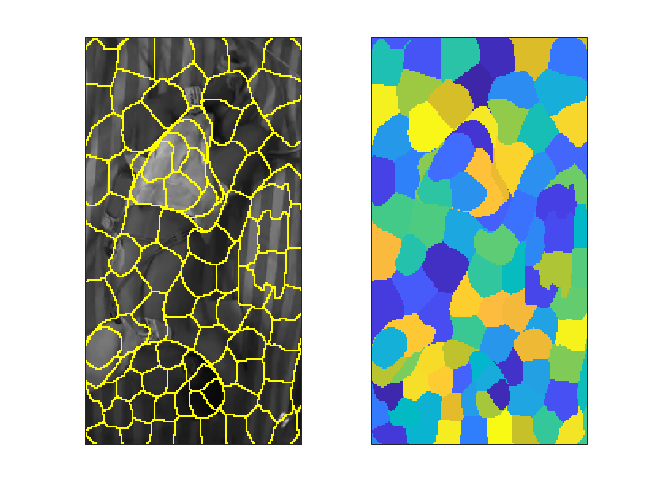

历时 36.591981 秒。
历时 13.010354 秒。
历时 13.929933 秒。
历时 10.164773 秒。
历时 9.951519 秒。


% 处理每帧
for frameIndex = 1:numFrames
    % 读取并预处理帧
    frame = read(videoObject, frameIndex);
    frame = imrotate(frame, 90);
    grayFrame = rgb2gray(frame);
    doubleFrame = double(grayFrame);

    % 图像分割
    tic;
    [SegmentationMask, lastcenters] = nonlinearSegmentation(doubleFrame, numClusters, intensityWeight, downsizeRatio,lastcenters,max_iterations);
    toc;

    % 显示结果
    subplot(1, 2, 1), imagesc(imoverlay(doubleFrame / 255, boundarymask(SegmentationMask), 'y')); % Mask轮廓
    set(gca, 'xtick', [], 'ytick', []);
    subplot(1, 2, 2), imagesc(SegmentationMask); % Mask标签
    set(gca, 'xtick', [], 'ytick', []);
    drawnow;

    % 写入视频
    frameOutput = getframe(gcf);
    writeVideo(videoOut, frameOutput);
end

close(videoOut);

function [SegmentationMask,lastcenters] = nonlinearSegmentation(doubleFrame, numClusters,intensityWeight, downsizeRatio,lastcenters,max_iterations)
% Preprocess the image
Frame_resized = imresize(doubleFrame,downsizeRatio);
Frame_filted = medfilt2(Frame_resized,[15,15]);

% Create feature vectors
[rows ,cols] = size(Frame_filted);
feature_matrix = zeros(rows*cols,3);
[x, y] = meshgrid(1:cols, 1:rows);
intensity =Frame_filted(:);
x = x(:);
y = y(:);
feature_matrix = [intensity * intensityWeight, x * (1 - intensityWeight), y * (1 - intensityWeight)];
 % c) K 均值聚类
[C, BestAssignments] = mykmeans(feature_matrix, numClusters,lastcenters,max_iterations);
lastcenters = C;
segmentationMask = reshape(BestAssignments, rows, cols);
SegmentationMask = imresize(segmentationMask, [size(doubleFrame, 1), size(doubleFrame, 2)], 'nearest');
end

function [C, bestAssignment] = mykmeans(X, K,lastcenters,max_iterations)
% Initialize cluster centers to be randomly sampled points
[N, d] = size(X);
if isempty(lastcenters)
        rp = randperm(N);
        C = X(rp(1:K), :);
else
     % 否则，使用提供的聚类中心
        C = lastcenters;
end
bestAssignment = zeros(N, 1);
while max_iterations
    lastAssignment = bestAssignment;
    % Assign each point to nearest cluster center
    mindist = Inf*ones(N, 1);
    for k = 1:K
        for n = 1:N
            dist = sum((X(n, :)-C(k, :)).^2);
            if dist < mindist(n)
               mindist(n) = dist;
               bestAssignment(n) = k;
            end
        end
    end
% break if assignment is unchanged
    if all(bestAssignment==lastAssignment)
        break; end
% Assign each cluster center to mean of
    for k = 1:K
    C(k, :) = mean(X(bestAssignment==k, :));
    end
end
end
